## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 4 - Nonlinear Solvers: Newton-Raphson Method**

**4.1 Linear and Nonlinear Solvers:**

Most of the deformable body systems we dealt with in undergraduate mechanics class are linear elastic. These include shaft twisted under applied torque, beams bented with applied moment, or bars compressed by axial forces. When studying their behaviors, we usually assume linear elastic material behaviors and infinitesimal deformation. With the sysetm being linear elastic, the internal forces of the system $F$ is uniquely corelated with the deformation $U$ with a stiffness matrix: 


$$\mathit{\mathbf{F}}=\textrm{KU}$$


or, we can also calculate the deformation of the system from the force as:


$$\mathit{\mathbf{U}}={\mathit{\mathbf{K}}}^{-1} \mathit{\mathbf{F}}$$


For most problems related to deformable bodies (and active structures), we normally want to find the equilibirum position of the body. To refresh our memory about undergraduate mechanics, equiligirum is achieved when the internal force is equal to the applied force:


$$\mathit{\mathbf{F}}={\mathit{\mathbf{F}}}_{\textrm{applied}\;}$$


Therefore, our goal is to find the deformation correlated to a specific applied load when studying many active structures or deformable bodies. This requires us to solve:


$$\mathit{\mathbf{U}}={\mathit{\mathbf{K}}}^{-1} {\mathit{\mathbf{F}}}_{\textrm{applied}}$$


In order to use the above equation, we normally need to assume that the system is linear ealstic and the deformation is infinitesimally small. For most of the deformable body under large deformation, the above equation is no longer true because the system behavior is nonlinear. The following two spring system is a good example to demonstrate this concept. If we solve the system using a linear solver under the applied upward force, we will see that the node j will only move upward. This is true when deformation is small (infinitesimal) but no longer true if the deformation is large. When the deformation is large, the node will be stretched towards left because the left spring is also stretched. 

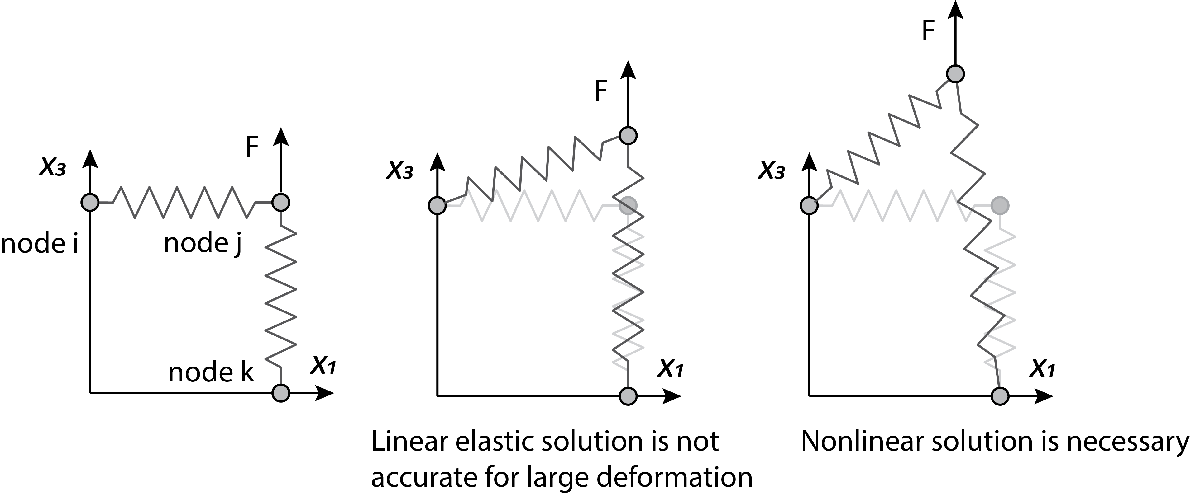

For the above nonlinear situtaion, we need to calculate the reaction force and stiffness matrix about the deformed configuraiton using nonlinear functions as:


$$\mathit{\mathbf{F}}=\mathit{\mathbf{F}}\left(\mathit{\mathbf{U}}\right)$$



$$\mathit{\mathbf{K}}=\mathit{\mathbf{K}}\left(\mathit{\mathbf{U}}\right)$$


This is what we did in the previous section_03. With the code ready, let's try to understand what is going on when we try to solve for the deformation of the system when the force is applied. 

**4.2 Linear Solver**

Let's first define the two spring system using the truss class. We can directly use the stock class file so that we do not need to rewrite any code for solving the global spring forces and stiffnesss matrix. 

% Create the node 
node=Elements_Nodes();
node.coordinates_mat=[0,0,1;
                      1,0,1;
                      1,0,0];
% Please note that we had added the additional y-axis as usual.

% Create the bars
bar=CD_Elements_Bars;
bar.node_ij_mat=[1,2;
                 2,3];
E=1;
A=1;
bar.E_vec=E*ones(2,1);
bar.A_vec=A*ones(2,1);
bar.Initialize(node);

This gives us the definetion needed for the 2 spring truss system. To create a linear solver, we need four major steps. First, we need to find the stiffness matrix of system when no deformation is applied. Second, we need to create the applied force vector. Third, we need to modify the stiffness matrix and applied force vector based on boundary conditions. Finally, we can solve for the deformed shape using linear algebra solver. Let's try to see how each step is implemented. 

Finding the stiffness matrix is straightfoward with the stock code:

% Find the stiffness matrix
stiff_mat=bar.Solve_Global_Stiff(node,zeros(3,3));

Seting up the applied force vector is also a straight foward step:

% Applied force vector
applied_f=zeros(9,1);
applied_f(6)=1;

Basically, all the element in the vector is zero, except for the sixth one. This is correlated to the node j for the z-direction. 

Then, we need to adjust the stiffness matrix and the applied force vector to account for the support conditions. One easy way to apply this boundary condition is to set the corresponding diagonal term in the global matrix to be a very large number for the restricted DOF. Here, for our system, both node i (node 1) and node k (node 3) are fully restricted while the node j (node 2) is restricted in y direction. Apply this constraint can be implemented as:

% Define a large number
largeNum=10^9;

% Adjust stiffness matrix
stiff_mat(1,1)=largeNum;  % Node i (node 1) x direction
stiff_mat(2,2)=largeNum;  % Node i (node 1) y direction
stiff_mat(3,3)=largeNum;  % Node i (node 1) z direction

stiff_mat(5,5)=largeNum;  % Node j (node 2) y direction

stiff_mat(7,7)=largeNum;  % Node k (node 3) x direction
stiff_mat(8,8)=largeNum;  % Node k (node 3) y direction
stiff_mat(9,9)=largeNum;  % Node k (node 3) z direction

% We should create a function for this
function K_ad=adjust_K(K_input,largeNum)
    K_ad=K_input;
    for i=[1,2,3,5,7,8,9]
       K_ad(i,i)=largeNum;  
    end
end

In addition to adjusting the stiffness matrix, we also need to set the applied load to be zero at locations where support is restricted. The applied load will directly be taken by the support so these forces will not go into the solution. We create a function for this:

function F_ad=adjust_F(F_input)
    F_ad=F_input;
    for i=[1,2,3,5,7,8,9]
       F_ad(i)=0; 
    end
end
% Now apply this adjustment to the force
applied_f=adjust_F(applied_f)

applied_f =      0
     0
     0
     0
     0
     1
     0
     0
     0


Then the deformation can be found through solving the linear system as:

% Find the deformation vector
U_linear=stiff_mat\applied_f

U_linear =          0
         0
    0.0000
         0
         0
    1.0000
         0
         0
    0.0000


The above results shows the deformation vector we found. The node j (node 2) is moved up in the Z-direction by unit 1 and the other nodes are not moving. We can also plot the deformed results using the following code. Here, in order to reuse the plotting codes for multiple times, we will create a function

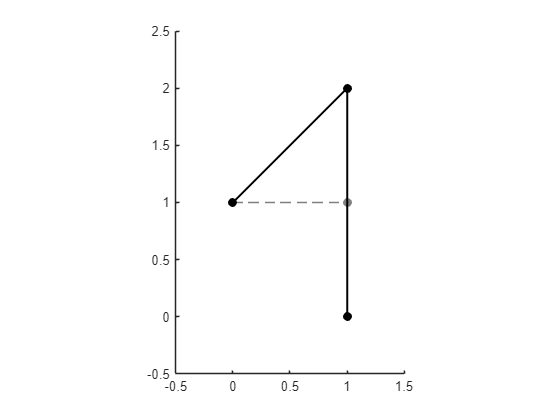

function Plot_DeformedShape(node,U_linear)
    % Plot the figgure
    figure
    hold on
    view(0,0); 
    set(gca,'DataAspectRatio',[1 1 1])
    axis([-0.5,1.5,-1,1,-0.5,2.5])
    
    % Find the coordinates
    Xi=node.coordinates_mat(1,:);
    Xj=node.coordinates_mat(2,:);
    Xk=node.coordinates_mat(3,:);
    xi=Xi+U_linear(1:3)'; 
    xj=Xj+U_linear(4:6)'; 
    xk=Xk+U_linear(7:9)';

    % Original bar location
    plot3([Xi(1),Xj(1)],[Xi(2),Xj(2)],[Xi(3),Xj(3)],...
        Color=[0.5,0.5,0.5], LineStyle='--',...
        Marker='.', MarkerSize=20)
    plot3([Xj(1),Xk(1)],[Xj(2),Xk(2)],[Xj(3),Xk(3)],...
        Color=[0.5,0.5,0.5], LineStyle='--',...
        Marker='.', MarkerSize=20)
    
    % Deformed bar location
    plot3([xi(1),xj(1)],[xi(2),xj(2)],[xi(3),xj(3)],...
        Color='black',Marker='.',...
        MarkerSize=20, LineWidth=1.5)
    plot3([xj(1),xk(1)],[xj(2),xk(2)],[xj(3),xk(3)],...
        Color='black',Marker='.',...
        MarkerSize=20, LineWidth=1.5)
end
Plot_DeformedShape(node,U_linear)

This is exactly what is shown in the previous figure. In this case, if the applied force is smaller (say F=0.001N), our solution is perfectly accurate because the deformation is indeed infinitesimal. For the above system, however, the linear solution looks very off from our mehcanical intuition - this is why we need nonlinear solution methods. 

One way to see why the linear solution scheme does not work here is to recompute the force vector of the system in the deformed configuration. We can do this with the following code:

% Reshape the matrix
U_linear_mat=reshape(U_linear,[3,3])'

U_linear_mat =          0         0    0.0000
         0         0    1.0000
         0         0    0.0000


% Find the force at the deformed configuration
nonlinear_force=bar.Solve_Global_Force(node,U_linear_mat);
nonlinear_force(6)

ans = 1.2929

We can see that the internal force in the z-direction is 1.29N and is larger than the 1.0N we applied. Thus, the found solution result actually does not satisfy the equilibirum condition. This is all because the deformation is too large - larger than what a linear solution scheme can handle. 

**4.3 Nonlinear Solver - Newton Raphson**

Here, we want to demonstrate how to use nonlinear solvers to address the limitations of linear solvers. Here, we will focus on the simplest nonlinear solver - a second order Newton-Raphson solver. Despite the simplicity, this solver is still the go-to solver for numerous applications. 

Before talking about Newton-Raphson, here is a great resource for learning other nonlinear solvers. This paper by Leon et. al. is an amazing resources to learn about different formulations of nonlinear solvers. 

[https://asmedigitalcollection.asme.org/appliedmechanicsreviews/article/64/4/040803/463373/A-Unified-Library-of-Nonlinear-Solution-Schemes](https://asmedigitalcollection.asme.org/appliedmechanicsreviews/article/64/4/040803/463373/A-Unified-Library-of-Nonlinear-Solution-Schemes)

Going back to the Newton-Raphson method. What the NR method will do is to break down the 1N load (A relatively large load for this system) into multiple smaller load and use iteration methods to correct the solution until we have $F_{\textrm{applied}} =F\left(U\right)$. The process is illustrated in the following figure. Each $\delta \;F_{\textrm{ext}}$ is the small load step that will eventually adds up to 1N. Every time we increase the load by $\delta \;F_{\textrm{ext}}$ we update the deformation iteratively so that the unbalanced load is minimized. 

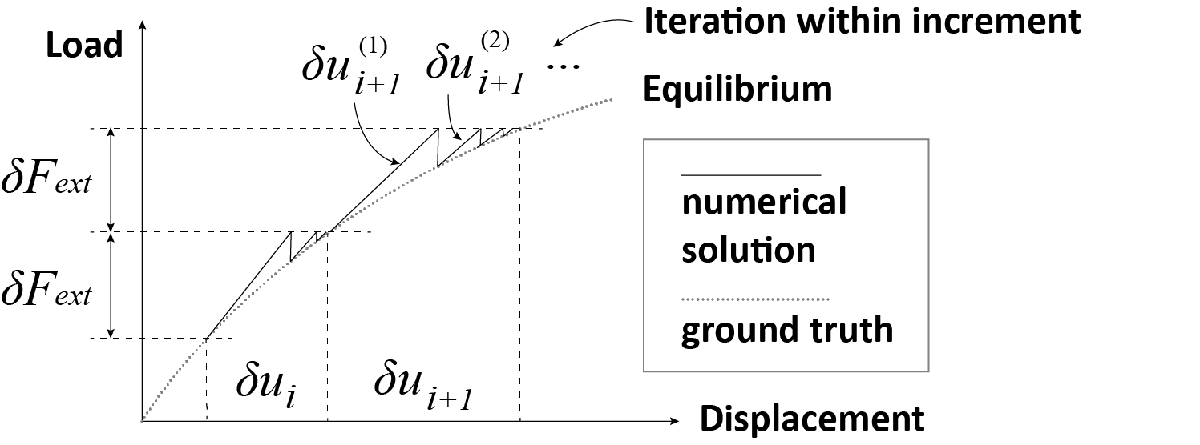

For instance, for the first step let's do a 0.5N load step

% first load step
delta_F=0.5;

% Get the applied force vector for the load step
applied_f=zeros(9,1);
applied_f(6)=applied_f(6)+delta_F;

% Current Deformation
U_current_mat=zeros(3,3);
U_current_vec=zeros(9,1);

% Find the stiffness matrix
stiff_mat=bar.Solve_Global_Stiff(node,zeros(3,3));

% Adjust the stiffness matrix for boundary condition
stiff_mat=adjust_K(stiff_mat,largeNum);

% Adjust the applied force vector
applied_f=adjust_F(applied_f);

% Find the deformation step
dU=stiff_mat\applied_f;

After this step we can check to see if we have everything in equilibirum:

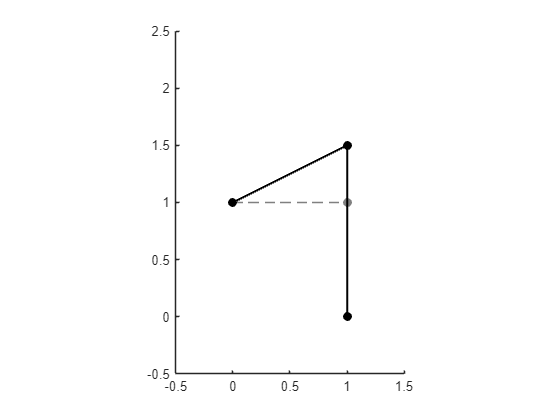

% Update the deformation
U_current_vec=U_current_vec+dU;
U_current_mat=reshape(U_current_vec,[3,3])';

% Internal force in structure
F_int=bar.Solve_Global_Force(node,U_current_mat);

% Plot the deformed shape
Plot_DeformedShape(node,U_current_vec);

Still, we only see the node move upward and we know that this is not true. We want to further compare the forces at the node j (node 2) to see how big a difference we have between the applied load and the actual internal node in the structure. 

F_int(6)

ans = 0.5528

applied_f(6)

ans = 0.5000

We can see that the internal force is not yet close to what the applied load is. Thus, we need to update the solution. The way we can update the solution is to find an additional deformation step using the "unbalanced" force between the internal response and the applied force. With the unbalanced force, we calculate another deformation step and add it to the solution. Please note that this time, we want to recalculate the stiffness matrix using the new nodal coordinates:

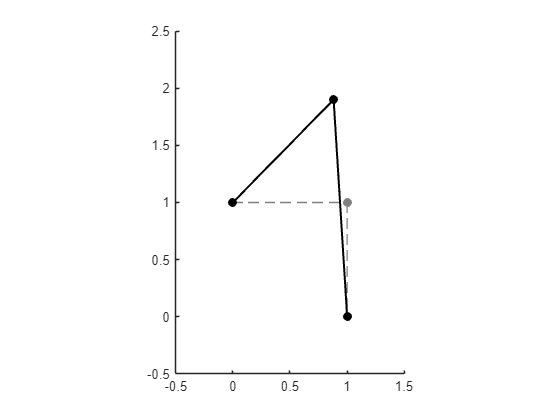

% Find the unbalanced load
unbalance=applied_f-F_int;

% Find the new stiffness matrix
stiff_mat=bar.Solve_Global_Stiff(node,U_current_mat);

% Adjust for boundary condition
stiff_mat=adjust_K(stiff_mat,largeNum);
unbalance=adjust_F(unbalance);
% Here instead of using the f_applied, we want to use the unbalance. 
% We want to find the deformation to minimize the unbalance. 

% Find the deformation step
dU=stiff_mat\applied_f;

% Update the deformation
U_current_vec=U_current_vec+dU;
U_current_mat=reshape(U_current_vec,[3,3])';

% Replot the structure
Plot_DeformedShape(node,U_current_vec);

Hmmm. it looks like this step over shoot a little for 0.5N of load, but I believe we are moving in the right direction! The node is moving left a little. The Newton-Raphson algorithm will repeat the above operation over and over again until it finds out that the deformation due to unbalance is small. This can be done using the following for loop (or while loop). 

step=1;
R=1;
while and(step<30,R>10^-6)
    % Find the new stiffness matrix
    stiff_mat=bar.Solve_Global_Stiff(node,U_current_mat);    
    % Internal force in structure
    F_int=bar.Solve_Global_Force(node,U_current_mat);    
    % Find the unbalanced load
    unbalance=applied_f-F_int;

    % Adjust for boundary condition
    stiff_mat=adjust_K(stiff_mat,largeNum);
    unbalance=adjust_F(unbalance);

    % Find the deformation step
    dU=stiff_mat\unbalance;

    % Update the deformation
    U_current_vec=U_current_vec+dU;
    U_current_mat=reshape(U_current_vec,[3,3])';

    R=norm(dU);
    step=step+1;        
end

In the above while loop, the R term is the deformation due to unbalance (called remainder), we want to keep runing the loop until R is smaller than ${10}^{-6\;}$, which is a small number. We keep counting the step, making sure that software will terminate if too many iterations are done. 

Let's see what we get:

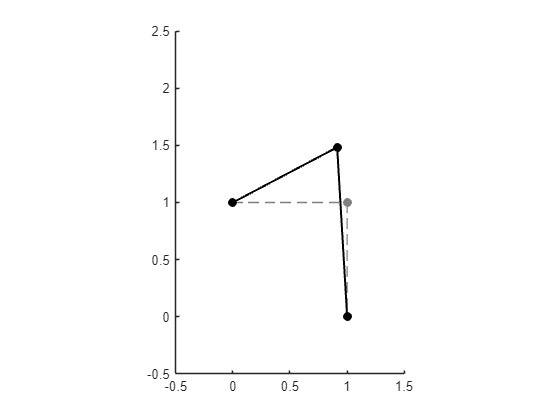

% Replot the structure
Plot_DeformedShape(node,U_current_vec);

OK! Nice! This looks just like what we want because the node is about 0.5 above its original position and is dragged to the left a little by the left spring. How do the forces look like?

F_int(6)

ans = 0.5000

applied_f(6)

ans = 0.5000

They also match each other perfectly! 

Cool! So the next thing we hope to do is further increase the applied load to 1N and update the deformation based on what we have. Let's see what we get here:

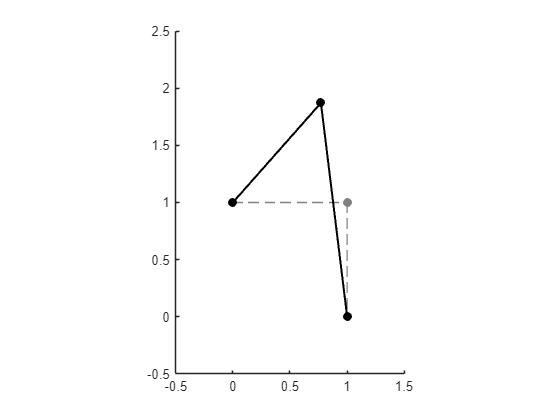

% Increase the applied_f for the increment step
applied_f(6)=applied_f(6)+delta_F;

% Redo the iteration loop
step=1;
R=1;
while and(step<30,R>10^-6)
    % Find the new stiffness matrix
    stiff_mat=bar.Solve_Global_Stiff(node,U_current_mat);    
    % Internal force in structure
    F_int=bar.Solve_Global_Force(node,U_current_mat);    
    % Find the unbalanced load
    unbalance=applied_f-F_int;

    % Adjust for boundary condition
    stiff_mat=adjust_K(stiff_mat,largeNum);
    unbalance=adjust_F(unbalance);

    % Find the deformation step
    dU=stiff_mat\unbalance;

    % Update the deformation
    U_current_vec=U_current_vec+dU;
    U_current_mat=reshape(U_current_vec,[3,3])';

    R=norm(dU);
    step=step+1;        
end
% Replot the structure
Plot_DeformedShape(node,U_current_vec);

The plot looks perfect!

F_int(6)

ans = 1.0000

applied_f(6)

ans = 1

The forces also matches perfectly!

Now, compare this solution with the linear solution, we see that using the nonlinear solution can dramatically increase the accuracy of the simulation. One reason why we break the 1N load into two 0.5N increment is that it helps the Newton's method to converge during the iteration. In general, the second order Newton's method can coverge to a solution as long as the starting position is "close enough" to the ground truth. However, there is not yet a mathematical theory that is available out there to quantitatively measure "close enough" so using the NR solver requires a little bit of trial and error. This is big topic to cover in math classes like "Numerical Method".  Anyway, we will not need to worry about these for now. 

The next section will show you how to use the stock NR solver to solve a simple structure. 